## Night 4:Homework One

This Homework simulate the '**Center of Mass' to the experiment we already had in the Class**

**Project i:1 dimension simulate**

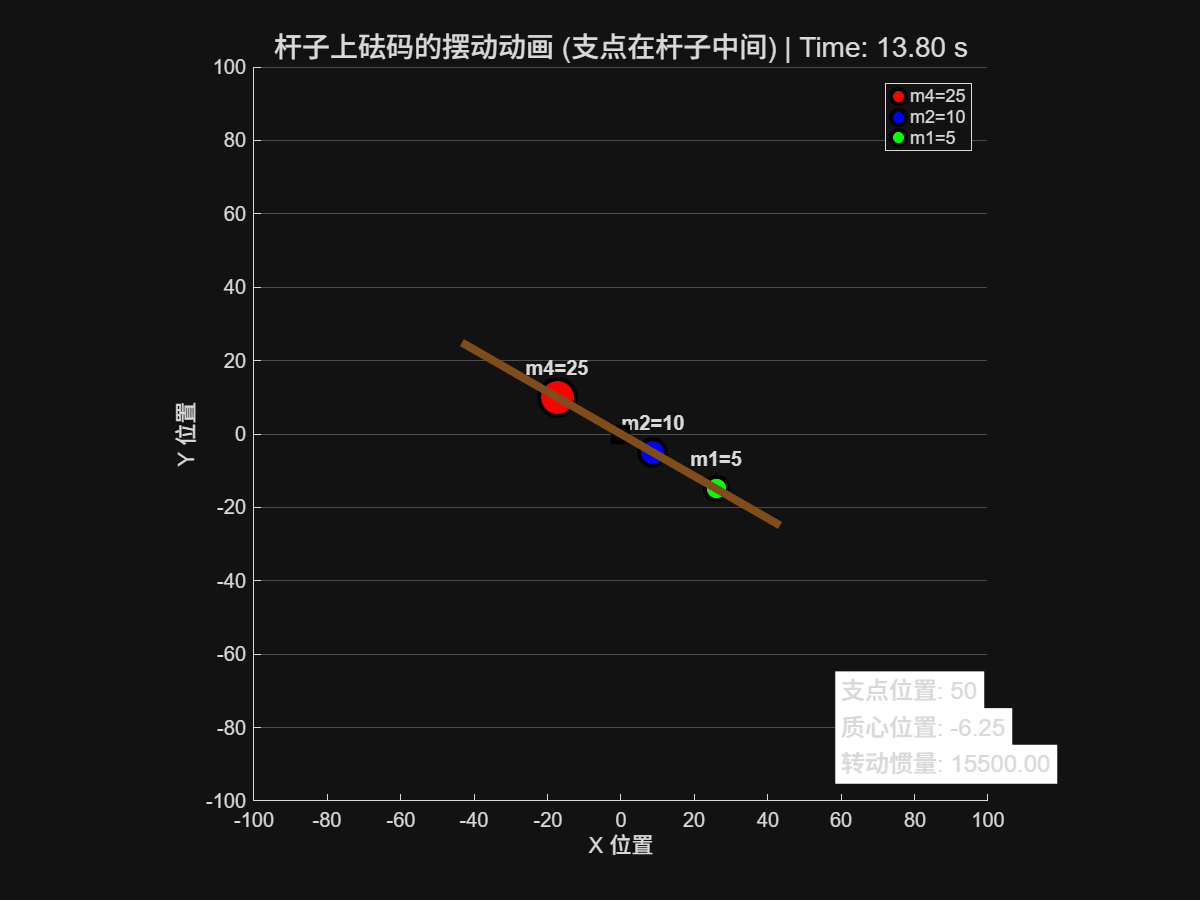

m2 = 10;
m3 = 15;
m4 = 25;
m5 = 50; % 砝码质量
m1 = 5;
g = 10; % 重力加速度

dt = 0.002; % 时间步长
T_mac = 14; % 模拟五秒

% 杆子长度和支点位置
Lenth = 100; % 杆子总长度
pivot_pos = 50; % 支点在杆子中间（50的位置）

% 砝码配置 - 位置是相对于杆子左端的位置
M = [m4, m2, m1]; % 砝码质量
posit = [30, 60, 80]; % 砝码在杆子上的位置（距离杆子左端的距离）

% 计算砝码相对于支点的位置（用于力矩计算）
relative_pos = posit - pivot_pos;

% 计算质心位置（相对于支点）
total_mass = sum(M);
x_oo = sum(M .* relative_pos) / total_mass;

% 计算转动惯量（绕支点）
I = sum(M .* relative_pos.^2);

% 初始条件 - 水平
theta0 = pi/12; 

n = floor(T_mac/dt); % 总步数

theta = zeros(n, 1); % 杆子和水平方向的夹角
omega = zeros(n, 1); % 角速度
t = zeros(n, 1); % 时间数组
x_mass = zeros(n, 3); % 3个砝码的x坐标
y_mass = zeros(n, 3); % 3个砝码的y坐标
x_pivot = zeros(n, 1); % 支点的x坐标（固定）
y_pivot = zeros(n, 1); % 支点的y坐标（固定）

% 初始条件
theta(1) = theta0; % 初始角位移
omega(1) = 0; % 初始角速度
t(1) = 0; % 初始时间
x_pivot(1) = 0; % 支点固定在原点
y_pivot(1) = 0; % 支点固定在原点

% 计算初始砝码位置（相对于支点）
for j = 1:3
    x_mass(1, j) = relative_pos(j) * cos(theta(1));
    y_mass(1, j) = relative_pos(j) * sin(theta(1));
end

% 使用欧拉法数值积分求解运动方程
for i = 1:n-1
    % 计算角加速度：α = - (m*g*R*sinθ)/I
    % 其中R是质心到支点的距离，即x_oo
    alpha = - (total_mass * g * x_oo * sin(theta(i))) / I;
    
    % 更新角速度：ω_{i+1} = ω_i + α_i * Δt
    omega(i+1) = omega(i) + alpha * dt;
    
    % 更新角位移：θ_{i+1} = θ_i + ω_i * Δt
    theta(i+1) = theta(i) + omega(i+1) * dt;
    
    % 更新时间
    t(i+1) = t(i) + dt;
    
    % 更新支点位置（固定）
    x_pivot(i+1) = 0;
    y_pivot(i+1) = 0;
    
    % 更新砝码位置坐标（相对于支点）
    for j = 1:3
        x_mass(i+1, j) = relative_pos(j) * cos(theta(i+1));
        y_mass(i+1, j) = relative_pos(j) * sin(theta(i+1));
    end
end

% 画图
figure('Position', [200, 200, 800, 600]);
hold on;
axis equal;
grid on;

% 设置坐标轴范围
axis_limit = 100;
xlim([-axis_limit, axis_limit]);
ylim([-axis_limit, axis_limit]);

colors = ['r', 'b', 'g']; 
mass_handles = gobjects(1, 3); % 预分配图形对象数组

% 初始化砝码图形对象
for j = 1:3
    mass_handles(j) = plot(x_mass(1, j), y_mass(1, j), 'o', ...
        'MarkerSize', 10 + M(j)/3, ... % 质量越大，圆圈越大
        'MarkerFaceColor', colors(j), ...
        'MarkerEdgeColor', 'k', ...
        'LineWidth', 2);
end

% 添加砝码标签
labels = {'m4=25', 'm2=10', 'm1=5'};
text_handles = gobjects(1, 3);
for j = 1:3
    text_handles(j) = text(x_mass(1, j), y_mass(1, j) + 8, labels{j}, ...
        'FontSize', 10, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

% 绘制支点
pivot_handle = plot(0, 0, 'ks', 'MarkerSize', 12, 'MarkerFaceColor', 'k');

% 绘制杆子 - 从支点到杆子两端
rod_length = Lenth/2; % 杆子半长
rod_handle = plot([-rod_length*cos(theta(1)), rod_length*cos(theta(1))], ...
                 [-rod_length*sin(theta(1)), rod_length*sin(theta(1))], ...
                 'Color', [0.5, 0.3, 0.1], 'LineWidth', 4);

% 动画循环
skip_frames = 100; % 跳帧数
for i = 1:skip_frames:n
    % 更新杆子位置
    set(rod_handle, ...
        'XData', [-rod_length*cos(theta(i)), rod_length*cos(theta(i))], ...
        'YData', [-rod_length*sin(theta(i)), rod_length*sin(theta(i))]);
    
    % 更新砝码位置
    for j = 1:3
        set(mass_handles(j), 'XData', x_mass(i, j), 'YData', y_mass(i, j));
        
        % 更新砝码标签位置
        set(text_handles(j), 'Position', [x_mass(i, j), y_mass(i, j) + 8]);
    end
    
    % 更新时间显示
    time_text = sprintf('Time: %.2f s', t(i));
    title(['杆子上砝码的摆动动画 (支点在杆子中间) | ', time_text], 'FontSize', 14);
    
    % 刷新画面
    drawnow;
end

% 添加图例和说明
legend([mass_handles(1), mass_handles(2), mass_handles(3)], labels, 'Location', 'northeast');
xlabel('X 位置');
ylabel('Y 位置');

% 显示物理信息
text(60, -80, sprintf('质心位置: %.2f', x_oo), 'FontSize', 12, 'BackgroundColor', 'white');
text(60, -90, sprintf('转动惯量: %.2f', I), 'FontSize', 12, 'BackgroundColor', 'white');
text(60, -70, sprintf('支点位置: %d', pivot_pos), 'FontSize', 12, 'BackgroundColor', 'white');

hold off;

set(gca, "XGrid", "off", "YGrid", "on")

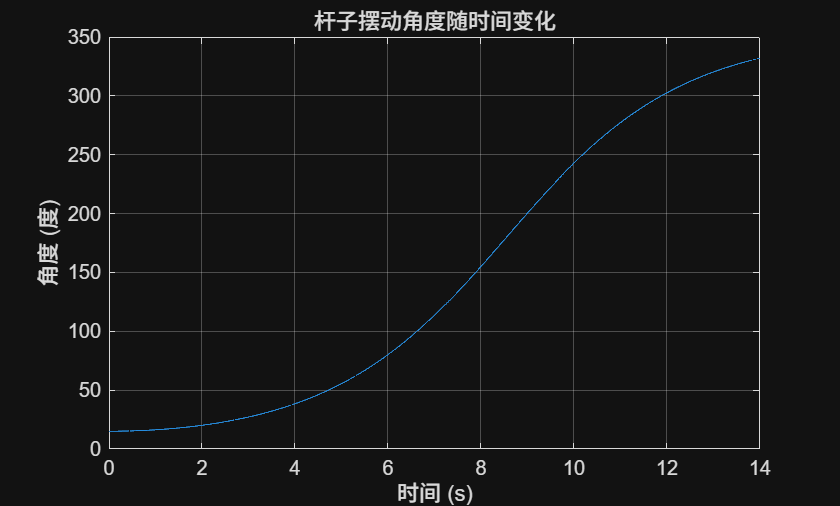


% 绘制角度随时间变化的曲线
figure;
plot(t, theta * 180/pi); % 转换为角度
xlabel('时间 (s)');
ylabel('角度 (度)');
title('杆子摆动角度随时间变化');
grid on;

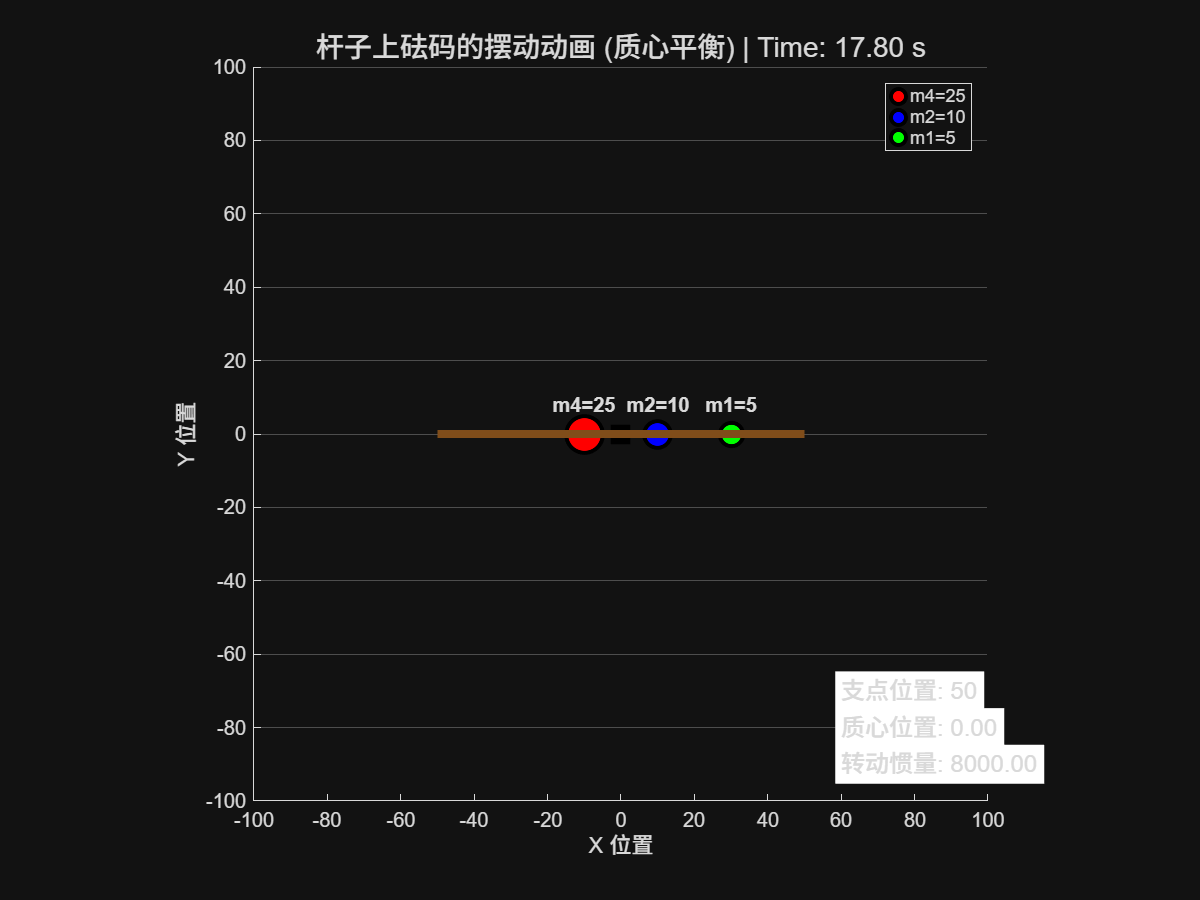


m1 = 5;
m2 = 10;
m3 = 15;
m4 = 25;
m5 = 50; % 砝码质量

g = 10; % 重力加速度

dt = 0.002; % 时间步长
T_mac = 18; % 模拟五秒

% 杆子长度和支点位置
Lenth = 100; % 杆子总长度
pivot_pos = 50; % 支点在杆子中间（50的位置）

% 砝码配置 - 位置是相对于杆子左端的位置
M = [m4, m2, m1]; % 砝码质量
posit = [40, 60, 80]; % 砝码在杆子上的位置（距离杆子左端的距离）

% 计算砝码相对于支点的位置（用于力矩计算）
relative_pos = posit - pivot_pos;

% 计算质心位置（相对于支点）
total_mass = sum(M);
x_oo = sum(M .* relative_pos) / total_mass;

% 计算转动惯量（绕支点）
I = sum(M .* relative_pos.^2);

% 初始条件 - 水平
theta0 = 0; 

n = floor(T_mac/dt); % 总步数

theta = zeros(n, 1); % 杆子和水平方向的夹角
omega = zeros(n, 1); % 角速度
t = zeros(n, 1); % 时间数组
x_mass = zeros(n, 3); % 3个砝码的x坐标
y_mass = zeros(n, 3); % 3个砝码的y坐标
x_pivot = zeros(n, 1); % 支点的x坐标（固定）
y_pivot = zeros(n, 1); % 支点的y坐标（固定）

% 初始条件
theta(1) = theta0; % 初始角位移
omega(1) = 0; % 初始角速度
t(1) = 0; % 初始时间
x_pivot(1) = 0; % 支点固定在原点
y_pivot(1) = 0; % 支点固定在原点

% 计算初始砝码位置（相对于支点）
for j = 1:3
    x_mass(1, j) = relative_pos(j) * cos(theta(1));
    y_mass(1, j) = relative_pos(j) * sin(theta(1));
end

% 使用欧拉法数值积分求解运动方程
for i = 1:n-1
    % 计算角加速度：α = - (m*g*R*sinθ)/I
    % 其中R是质心到支点的距离，即x_oo
    alpha = - (total_mass * g * x_oo * sin(theta(i))) / I;
    
    % 更新角速度：ω_{i+1} = ω_i + α_i * Δt
    omega(i+1) = omega(i) + alpha * dt;
    
    % 更新角位移：θ_{i+1} = θ_i + ω_i * Δt
    theta(i+1) = theta(i) + omega(i+1) * dt;
    
    % 更新时间
    t(i+1) = t(i) + dt;
    
    % 更新支点位置（固定）
    x_pivot(i+1) = 0;
    y_pivot(i+1) = 0;
    
    % 更新砝码位置坐标（相对于支点）
    for j = 1:3
        x_mass(i+1, j) = relative_pos(j) * cos(theta(i+1));
        y_mass(i+1, j) = relative_pos(j) * sin(theta(i+1));
    end
end

% 画图
figure('Position', [200, 200, 800, 600]);
hold on;
axis equal;
grid on;

% 设置坐标轴范围
axis_limit = 100;
xlim([-axis_limit, axis_limit]);
ylim([-axis_limit, axis_limit]);

colors = ['r', 'b', 'g']; 
mass_handles = gobjects(1, 3); % 预分配图形对象数组

% 初始化砝码图形对象
for j = 1:3
    mass_handles(j) = plot(x_mass(1, j), y_mass(1, j), 'o', ...
        'MarkerSize', 10 + M(j)/3, ... % 质量越大，圆圈越大
        'MarkerFaceColor', colors(j), ...
        'MarkerEdgeColor', 'k', ...
        'LineWidth', 2);
end

% 添加砝码标签
labels = {'m4=25', 'm2=10', 'm1=5'};
text_handles = gobjects(1, 3);
for j = 1:3
    text_handles(j) = text(x_mass(1, j), y_mass(1, j) + 8, labels{j}, ...
        'FontSize', 10, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

% 绘制支点
pivot_handle = plot(0, 0, 'ks', 'MarkerSize', 12, 'MarkerFaceColor', 'k');

% 绘制杆子 - 从支点到杆子两端
rod_length = Lenth/2; % 杆子半长
rod_handle = plot([-rod_length*cos(theta(1)), rod_length*cos(theta(1))], ...
                 [-rod_length*sin(theta(1)), rod_length*sin(theta(1))], ...
                 'Color', [0.5, 0.3, 0.1], 'LineWidth', 4);

% 动画循环
skip_frames = 100; % 跳帧加速
for i = 1:skip_frames:n
    % 更新杆子位置
    set(rod_handle, ...
        'XData', [-rod_length*cos(theta(i)), rod_length*cos(theta(i))], ...
        'YData', [-rod_length*sin(theta(i)), rod_length*sin(theta(i))]);
    
    % 更新砝码位置
    for j = 1:3
        set(mass_handles(j), 'XData', x_mass(i, j), 'YData', y_mass(i, j));
        
        % 更新砝码标签位置
        set(text_handles(j), 'Position', [x_mass(i, j), y_mass(i, j) + 8]);
    end
    
    % 更新时间显示
    time_text = sprintf('Time: %.2f s', t(i));
    title(['杆子上砝码的摆动动画 (质心平衡) | ', time_text], 'FontSize', 14);
    
    % 刷新画面
    drawnow;
end

% 添加图例和说明
legend([mass_handles(1), mass_handles(2), mass_handles(3)], labels, 'Location', 'northeast');
xlabel('X 位置');
ylabel('Y 位置');

% 显示物理信息
text(60, -80, sprintf('质心位置: %.2f', x_oo), 'FontSize', 12, 'BackgroundColor', 'white');
text(60, -90, sprintf('转动惯量: %.2f', I), 'FontSize', 12, 'BackgroundColor', 'white');
text(60, -70, sprintf('支点位置: %d', pivot_pos), 'FontSize', 12, 'BackgroundColor', 'white');

hold off;

set(gca, "XGrid", "off", "YGrid", "on")

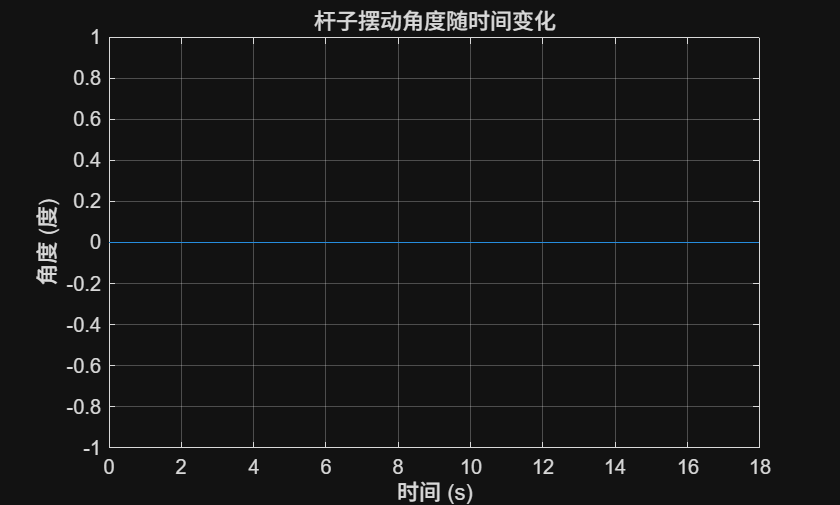


% 绘制角度随时间变化的曲线
figure;
plot(t, theta * 180/pi); % 转换为角度
xlabel('时间 (s)');
ylabel('角度 (度)');
title('杆子摆动角度随时间变化');
grid on;

**Project ii:2 dimension simulate**

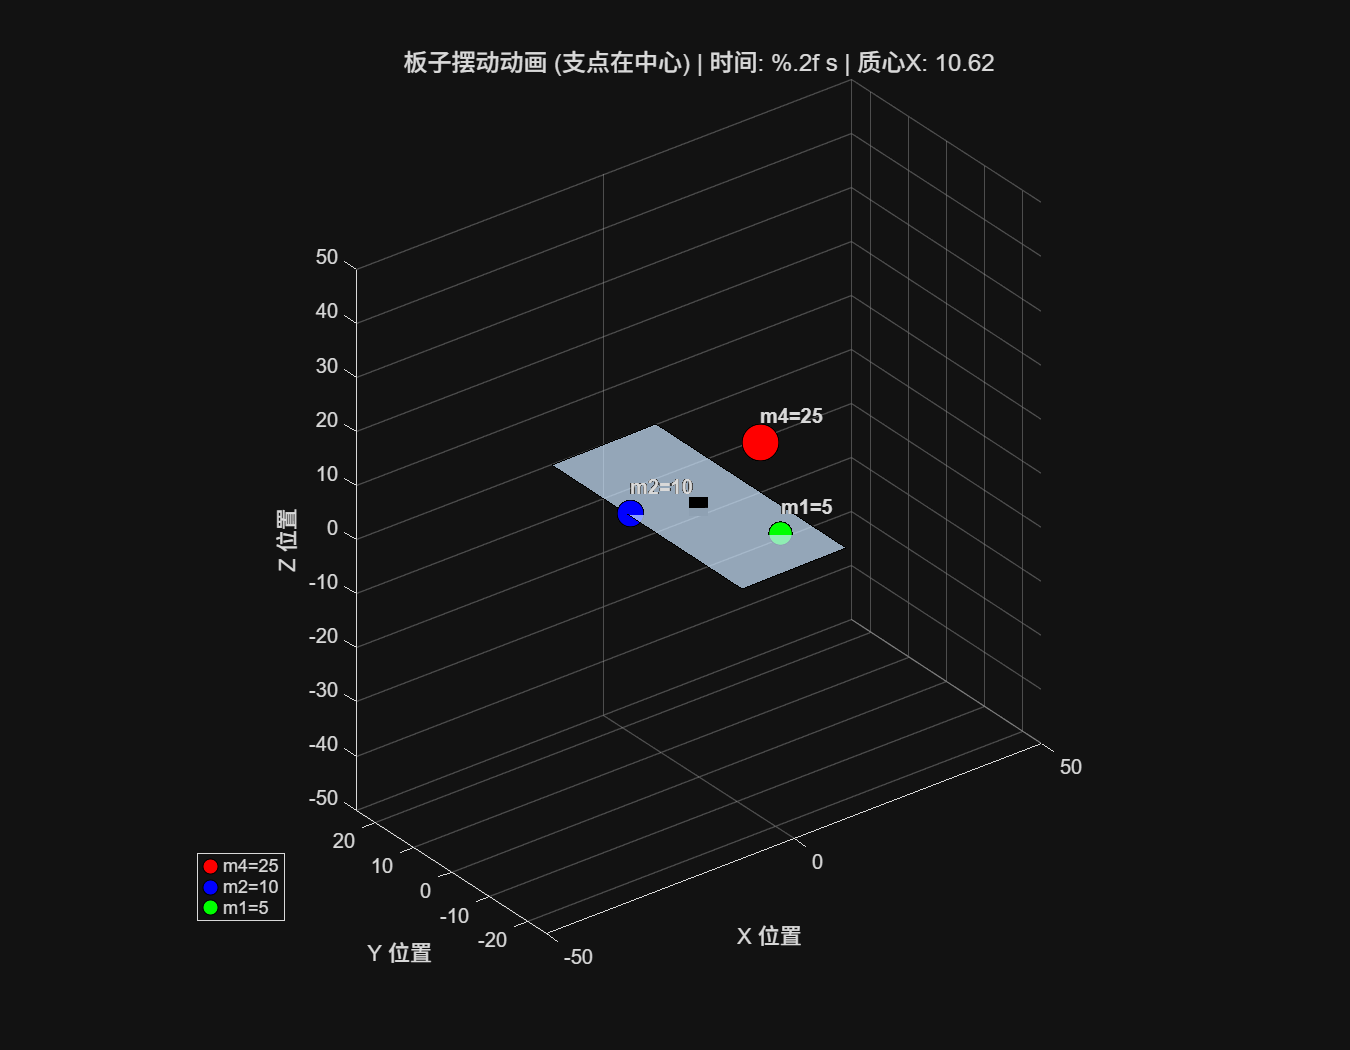



% 1. 定义板子尺寸（亚克力板，质量不计）
L = 100; % 板子长度（X方向）
W = 50;  % 板子宽度（Y方向，垂直于摆动平面）

% 2. 砝码位置：板子坐标系 (x_b, y_b) 相对于支点
M = [25, 10, 5]; % 质量 (kg)
x_b = [20, -10, 5]; % 板子坐标系X (单位：长度)
y_b = [10, 5, -15]; % 板子坐标系Y (单位：长度)

% 3. 计算质心（X方向，Y方向不影响运动）
total_mass = sum(M);
x_c = sum(M .* x_b) / total_mass; % 质心X坐标（板子坐标系）
I_y = sum(M .* x_b.^2); % 转动惯量（绕Y轴，因Z=0初始）

% 4. 初始条件（theta从垂直方向）
theta0 = pi/12; % 初始角度（15°，从垂直方向偏移）

% 5. 数值积分（物理方程不变）
n = floor(T_mac/dt);
theta = zeros(n, 1);
omega = zeros(n, 1);
t = zeros(n, 1);
theta(1) = theta0;
omega(1) = 0;
t(1) = 0;

for i = 1:n-1
    % 运动方程
    alpha = - (total_mass * g * x_c * sin(theta(i))) / I_y;
    omega(i+1) = omega(i) + alpha * dt;
    theta(i+1) = theta(i) + omega(i+1) * dt;
    t(i+1) = t(i) + dt;
end


figure('Position', [200, 200, 900, 700]);
hold on;
grid on;
axis equal;
view(3); % 3D视角

% 设置坐标轴范围（Z轴加高度）
xlim([-L/2, L/2]);
ylim([-W/2, W/2]);
zlim([-L/2, L/2]); % 为Z轴留空间

% 绘制初始板子（矩形，XY平面，Z=0）
plate_corners = [ -L/2, -W/2, 0; 
                 -L/2,  W/2, 0;
                  L/2,  W/2, 0;
                  L/2, -W/2, 0 ];
plate_patch = patch(plate_corners(:,1), plate_corners(:,2), plate_corners(:,3), [0.8, 0.9, 1], 'FaceAlpha', 0.7, 'EdgeColor', 'k');

% 绘制砝码（3D点）
colors = ['r', 'b', 'g'];
mass_handles = gobjects(1, 3);
for j = 1:3
    % 初始位置（3D）
    x0 = x_b(j) * cos(theta(1));
    y0 = y_b(j);
    z0 = -x_b(j) * sin(theta(1)); % 绕Y轴旋转
    mass_handles(j) = plot3(x0, y0, z0, 'o', 'MarkerSize', 10 + M(j)/3, ...
        'MarkerFaceColor', colors(j), 'MarkerEdgeColor', 'k');
end

% 添加标签
labels = {'m4=25', 'm2=10', 'm1=5'};
text_handles = gobjects(1, 3);
for j = 1:3
    x0 = x_b(j) * cos(theta(1));
    y0 = y_b(j);
    z0 = -x_b(j) * sin(theta(1));
    text_handles(j) = text(x0, y0, z0 + 5, labels{j}, 'FontSize', 10, 'FontWeight', 'bold');
end

% 添加支点（中心点）
pivot_handle = plot3(0, 0, 0, 'ks', 'MarkerSize', 12, 'MarkerFaceColor', 'k');

% 3D动画循环
skip_frames = 100; % 跳帧加速
for i = 1:skip_frames:n
    % 更新板子位置（绕Y轴旋转）
    for k = 1:4
        x_rot = plate_corners(k,1) * cos(theta(i));
        y_rot = plate_corners(k,2);
        z_rot = -plate_corners(k,1) * sin(theta(i));
        plate_corners(k,:) = [x_rot, y_rot, z_rot];
    end
    set(plate_patch, 'XData', plate_corners(:,1), 'YData', plate_corners(:,2), 'ZData', plate_corners(:,3));
    
    % 更新砝码位置
    for j = 1:3
        x_world = x_b(j) * cos(theta(i));
        y_world = y_b(j);
        z_world = -x_b(j) * sin(theta(i));
        set(mass_handles(j), 'XData', x_world, 'YData', y_world, 'ZData', z_world);
        set(text_handles(j), 'Position', [x_world, y_world, z_world + 5]);
    end
    
    % 更新标题
    title(['板子摆动动画 (支点在中心) | 时间: %.2f s', sprintf(' | 质心X: %.2f', x_c)], 'FontSize', 12);
    
    % 刷新画面
    drawnow;
end

% 添加图例和说明
legend(mass_handles, labels, 'Location', 'best');
xlabel('X 位置');
ylabel('Y 位置');
zlabel('Z 位置');
hold off;